% Default tree shew optics
theOI = oiTreeShrewCreate('name', 'default optics');

% Generate a cone mosaic
theConeMosaic = coneMosaicTreeShrewCreate(...
    theOI.optics.micronsPerDegree, ...
    'lConeDensity', 0.5,...
    'coneSeparationMicrons', 10, ...
    'innerSegmentDiameterMicrons', 6, ...
    'fovDegs', 1*[1.5 1.0], ...
    'integrationTime', 5/1000);

peakOpticalDensitiesLS =     0.0370    0.0389



Resampling grid. Please wait ... Done !
Will not change the S-cone density.
Scones before making an S-cone free central patch: 48
Scones after making an S-cone free central patch: 48 (added Lcones:0, added Mcones:0)
Scones after pass 1: 48 (added Lcones:0, added Mcones:0)


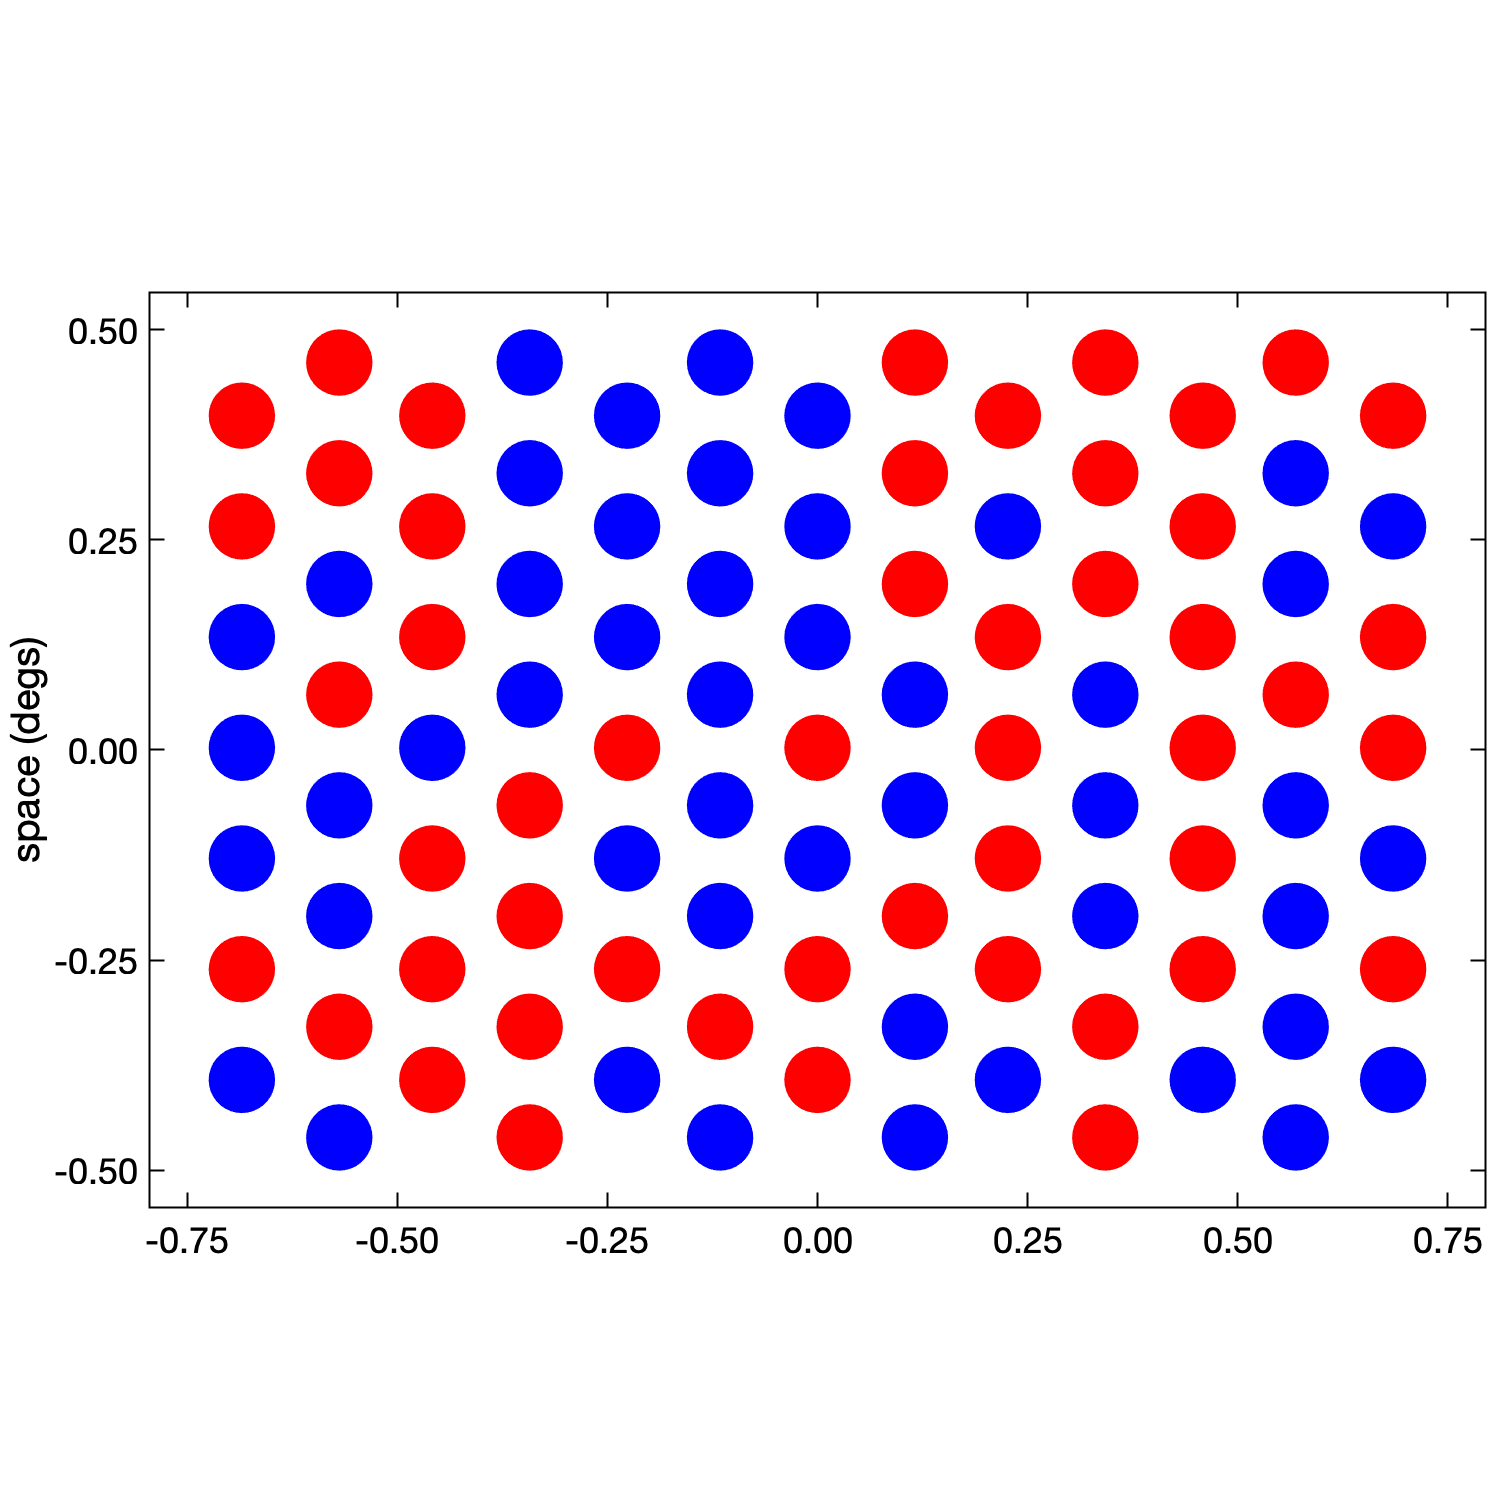


theConeMosaic.visualizeGrid(...
    'backgroundColor', [1 1 1], ...
    'generateNewFigure', true, ...
    'displayVisualDegs', false);

theConeMosaic.displayInfo();


Mosaic info:
                                      Size (microns): 118.0 (w) x 80.0 (h)
                                           FOV (deg): 1.55 (w) x 1.05 (h)
                                   Retinal coverages: 0.308 (aperture) x 0.857 (geometric)
                              Grid resampling factor: 5
                   Inner segment diameter (microns):  Min=1.5859, Mean=2.6421, Median=2.6725, Max=3.2421 
                     Inner segment area (microns^2):  Min=1.9752, Mean=5.4828, Median=5.6096, Max=8.2555 
                     Cone geometric area (microns^2): 78.5398 
               Cone light colleting area (microns^2): 28.2743
                                    Rectangular grid: 15 cols x 10 rows
                                      Resampled grid: 295 cols x 200 rows
                                         Total cones: 59000
                                        Active cones: 97
                                            L- cones: 49 (0.505%)
                        

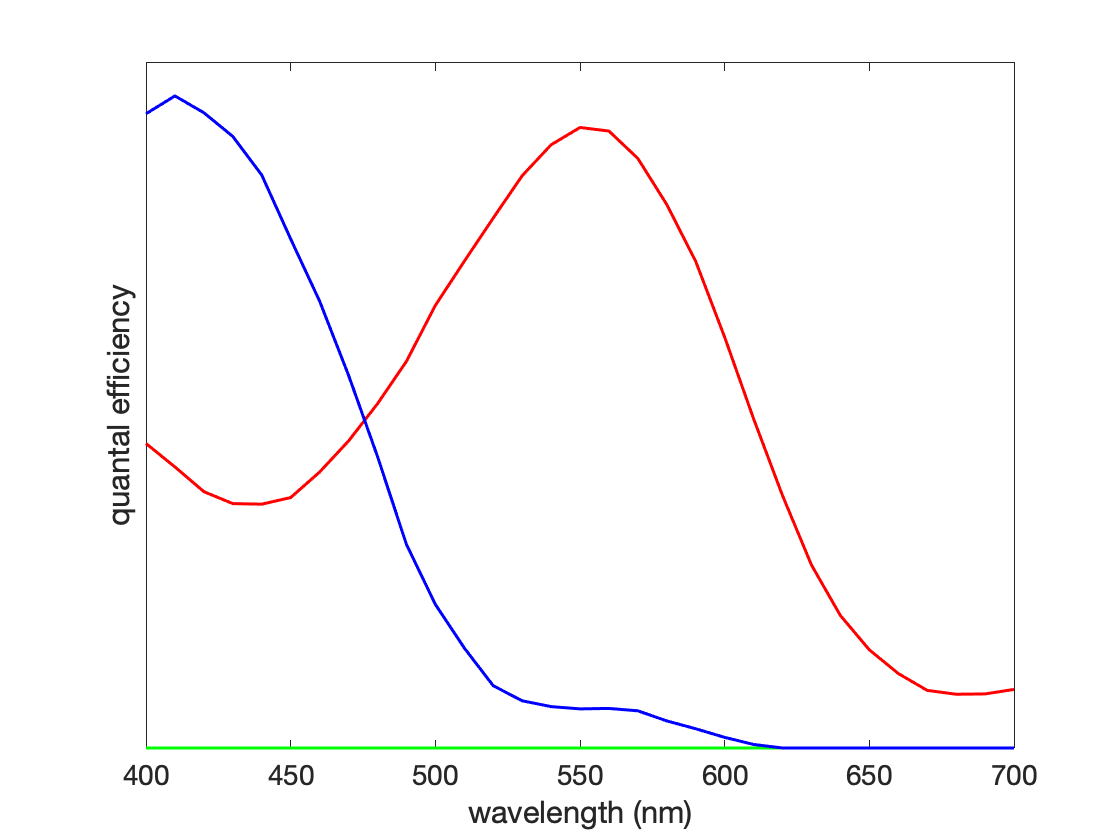

wavelength = theConeMosaic.wave;
quantalEfficiencies = theConeMosaic.qe;
figure(); clf;
plot(wavelength, quantalEfficiencies(:,1), 'r-', 'LineWidth', 1.5); hold on
plot(wavelength, quantalEfficiencies(:,2), 'g-', 'LineWidth', 1.5);
plot(wavelength, quantalEfficiencies(:,3), 'b-', 'LineWidth', 1.5);
set(gca, 'YTick', []);
set(gca, 'FontSize', 14)
xlabel('wavelength (nm)')
ylabel('quantal efficiency')